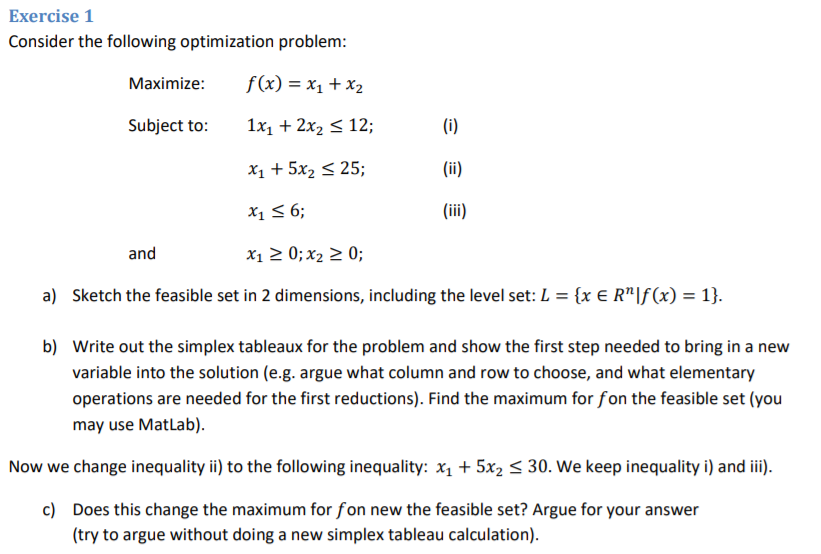

## Given

syms x1 x2
A = [   1 2 1 0 0 0;
        1 5 0 1 0 0;
        1 0 0 0 1 0];
b = [ 12;25;6];
c = -[1;1;0; 0; 0; -1 ];
v = [3;4;5];

%a
%Feasible set:
% Define function and constraints
h1 = @(x1,x2) x1+5*x2-25

h1 = function_handle with value:
    @(x1,x2)x1+5*x2-25


h2 = @(x1,x2) x1-6

h2 = function_handle with value:
    @(x1,x2)x1-6


h3 = @(x1,x2) x1+2*x2 - 12

h3 = function_handle with value:
    @(x1,x2)x1+2*x2-12


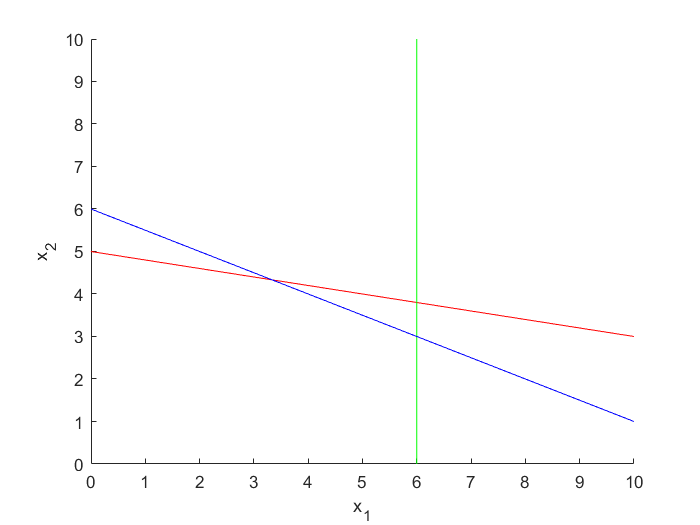



% Prepare plot
x1 = linspace(0,10);
x2 = linspace(0,10);
[X1,X2] = meshgrid(x1,x2);
figure
xlabel('x_1')
ylabel('x_2')
hold on


% (i)
contour(X1,X2,h1(X1,X2),[0,0],'r')
% (ii)
contour(X1,X2,h2(X1,X2),[0,0],'g')
% (iii)
contour(X1,X2,h3(X1,X2),[0,0],'b')
hold off



%b
simplex(c,A,b,v,1)

 
Initial tableau:
  Column 1

       1       
       1       
       1       
      -1       

  Column 2

       2       
       5       
       0       
      -1       

  Column 3

       1       
       0       
       0       
       0       

  Column 4

       0       
       1       
       0       
       0       

  Column 5

       0       
       0       
       1       
       0       

  Column 6

       0       
       0       
       0       
       1       

  Column 7

      12       
      25       
       6       
       0       

Pivot point:
  Column 1

       3       

  Column 2

       1       

New tableau:
  Column 1

       0       
       0       
       1       
       0       

  Column 2

       2       
       5       
       0       
      -1       

  Column 3

       1       
       0       
       0       
       0       

  Column 4

       0       
       1       
       0       
       0       

  Column 5

      -1       
      -1       
      

ans =        6       
       3       
       0       
       4       
       0       
       0       


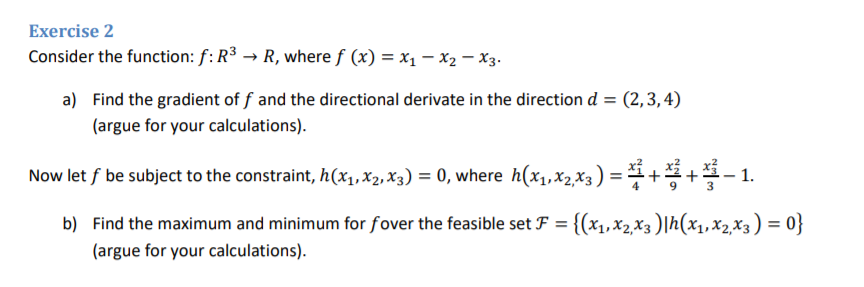

clear
syms x1 x2 x3
f = @(x1,x2,x3) x1 - x2 - x3;
h = @(x1,x2,x3) x1^2/5 +x2^2/9 + x3^2/3 - 1;

df1_x1 = diff(f,x1);
df1_x2 = diff(f,x2);
df1_x3 = diff(f,x3);
Df = [df1_x1 df1_x2 df1_x3];
gradient = Df';

$$gradient = \left(\begin{array}{c} 1\\ -1\\ -1 \end{array}\right)$$

gradient = matlabFunction(gradient)

gradient = function_handle with value:
    @()[1.0;-1.0;-1.0]




d = [2 3 4]';

d =        2       
       3       
       4       


d = d./norm(d);

d =     1119/3013  
    1820/3267  
    2521/3394  



norm(d);

ans =        1       



dir_dev = dot(d, Df)

$$dir\_dev = -\frac{5\,\sqrt{29}}{29}$$


%D2f = [diff(f, x1, x1) diff(f, x1, x2) diff(f, x1, x3);
%    diff(f, x2, x1) diff(f, x2, x2) diff(f, x2, x3);
%    diff(f, x3, x1) diff(f, x3, x2) diff(f, x3, x3);
%   ]


syms lambda
l = f(x1,x2,x3)+lambda*h;

$$l = x_{1}-x_{2}-x_{3}+\lambda \,\left(\frac{{x_{1}}^{2}}{5}+\frac{{x_{2}}^{2}}{9}+\frac{{x_{3}}^{2}}{3}-1\right)$$


dlx1 = diff(l,x1);

$$dlx1 = \frac{2\,\lambda \,x_{1}}{5}+1$$

dlx2 = diff(l,x2);

$$dlx2 = \frac{2\,\lambda \,x_{2}}{9}-1$$

dlx3 = diff(l,x3);

$$dlx3 = \frac{2\,\lambda \,x_{3}}{3}-1$$

dll = diff(l,lambda);

$$dll = \frac{{x_{1}}^{2}}{5}+\frac{{x_{2}}^{2}}{9}+\frac{{x_{3}}^{2}}{3}-1$$


syms x1 x2 lambda
[x1, x2, x3, lambda] = solve(dlx1==0,dlx2==0,dlx3==0,dll==0, x1, x2, x3, lambda)

$$x1 = \left(\begin{array}{c} \frac{5\,\sqrt{17}}{17}\\ -\frac{5\,\sqrt{17}}{17} \end{array}\right)$$

$$x2 = \left(\begin{array}{c} -\frac{9\,\sqrt{17}}{17}\\ \frac{9\,\sqrt{17}}{17} \end{array}\right)$$

$$x3 = \left(\begin{array}{c} -\frac{3\,\sqrt{17}}{17}\\ \frac{3\,\sqrt{17}}{17} \end{array}\right)$$

$$lambda = \left(\begin{array}{c} -\frac{\sqrt{17}}{2}\\ \frac{\sqrt{17}}{2} \end{array}\right)$$


x1 = [5*sqrt(17)/17; -9*sqrt(17)/17; -3*sqrt(17)/17];
x2 = [-5*sqrt(17)/17; 9*sqrt(17)/17; 3*sqrt(17)/17];

f(x1(1),x1(2),x1(3))

ans =     2177/528   


f(x2(1),x2(2),x2(3))

ans =    -2177/528   
